# Plate Reader 2 -- experiment 2

## Step 1: data loading and preparation

Add PLATERO set of functions to your working directory:

my = version('-release');
if str2double(my(1:4))<2020
addpath(genpath('rprev2020'))
else
addpath(genpath('r2020'))
end

Now, load the data resulting from the calibration experiment, written in "`filename`". This data is organized by sheets, where each sheet has one repetition of the measurements.

filename = "PlateReader2_exp2.xlsx";
colnames = {'WellID','Well','Concentration','G50','G60','G70','G80','G90','G120'};
[dataPR, indgfp] = readexperiment(filename,"A7:I103",[50:10:90,120],false,...
    colnames,0);
iG = and(dataPR.Gain > 50, dataPR.Gain < 120);
dataPR = dataPR(iG, :);
indgfp = indgfp(iG, :);
size(dataPR)

ans =         3072           5


Divide the dataset into the subset with medium values (`dataPRblk`) and the set with fluorescein values (`dataPRgfp`).

datPRblk = dataPR(~indgfp,:);
datPRgfp = dataPR(indgfp,:);
disp(strcat("This data set has ", string(size(datPRblk,1)),...
" BLK observations and ", string(size(datPRgfp,1)), ...
" GFP observations."))

This data set has 512 BLK observations and 2560 GFP observations.


Obtain the partition of the fluorescein dataset into the model building set  (70%) and the model validation set (30%). A seed is set to ensure reproducibility of the results. The resulting subsets are stored as the `calibration_PR1.mat `and the `validation_PR1.mat `files.

rng(0207)
[datagfp_cal, datagfp_val] = cvsplit(datPRgfp, 0.7);
disp(strcat("The calibration data set has ", string(size(datagfp_cal,1)),...
    " observations and the validation data set has ", ...
    string(size(datagfp_val,1)), " observations."))

The calibration data set has 1760 observations and the validation data set has 800 observations.


data_cal_pr2e2 = [datPRblk; datagfp_cal];
save('calibration_PR2e2.mat',"data_cal_pr2e2")
save('validation_PR2e2.mat',"datagfp_val")

## Step 2: Model Building step

Load the calibration subset, fit the model and store the coefficients.

Explorative plot of missing data for each concentration level: 


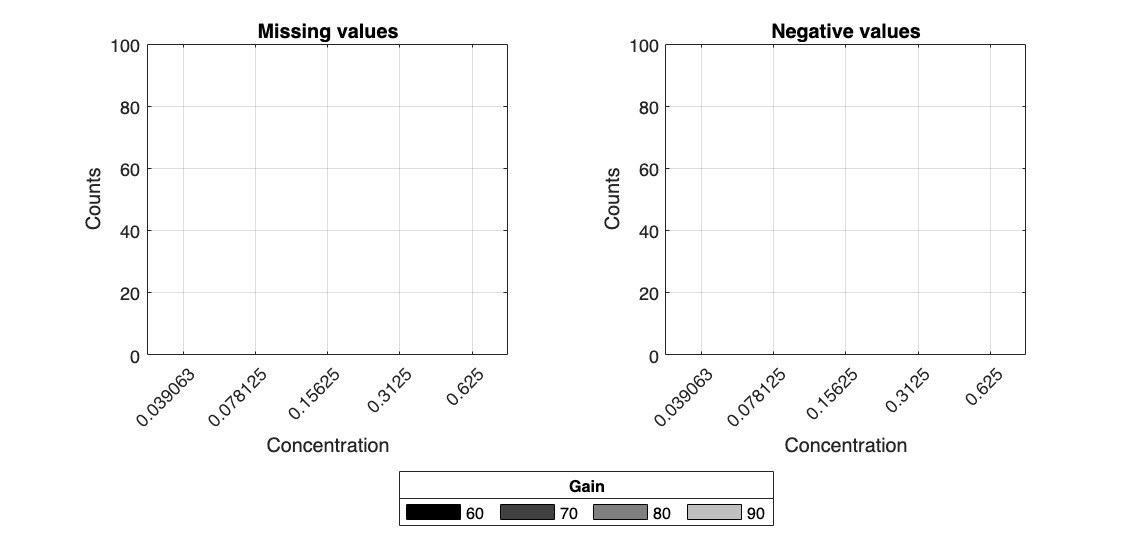

Concentration(s) had missing values
Concentration(s) had negative values
Gain(s) had missing values
Gain(s) had negative values
Explorative plot of the raw F_observed Fluorescein data: 


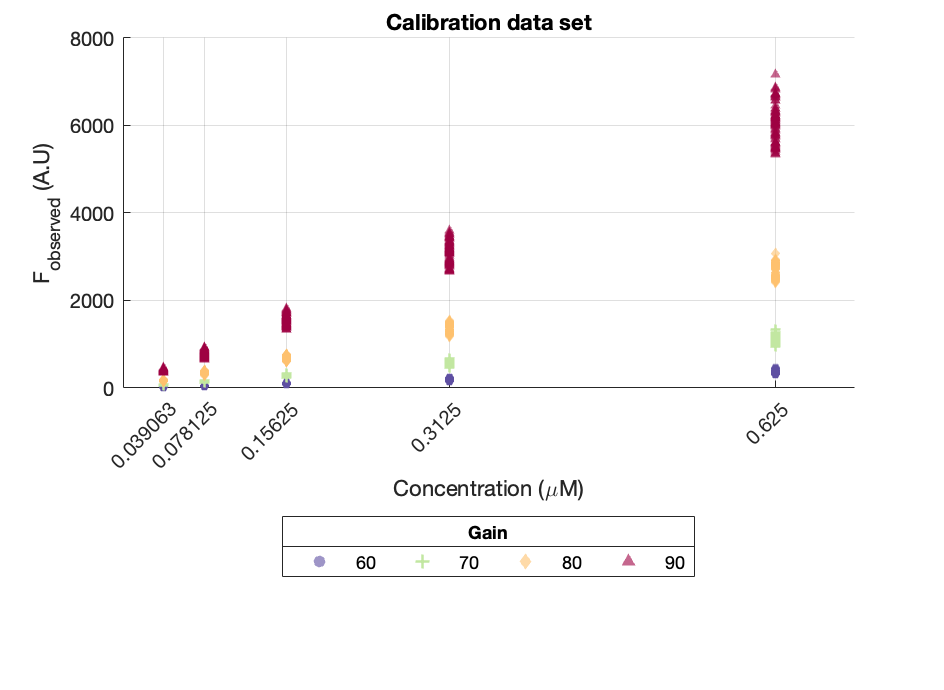

Explorative plot of the raw F_BLK data: 


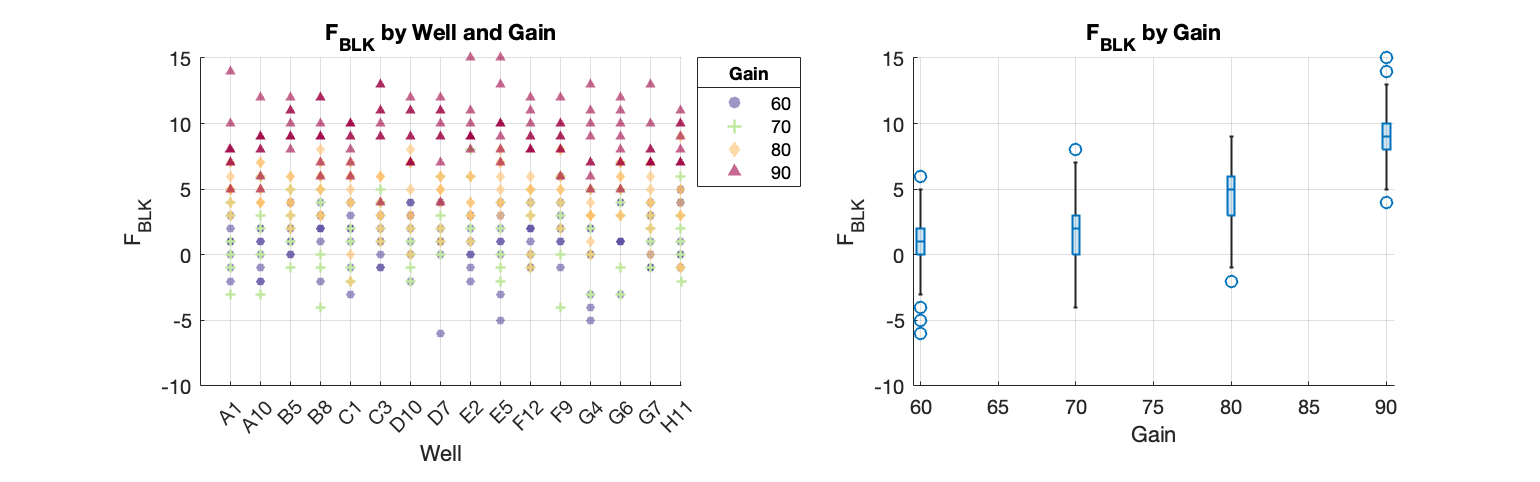

data_cal_pr2e2 = load("calibration_PR2e2.mat").data_cal_pr2e2;
[blk_data, flu_data_PR2e2] = explore_data(data_cal_pr2e2, 0);

Fit f_G and plot corrected data (F_reporter): 
ANOVA on coefficient b_1 for all levels of concentration


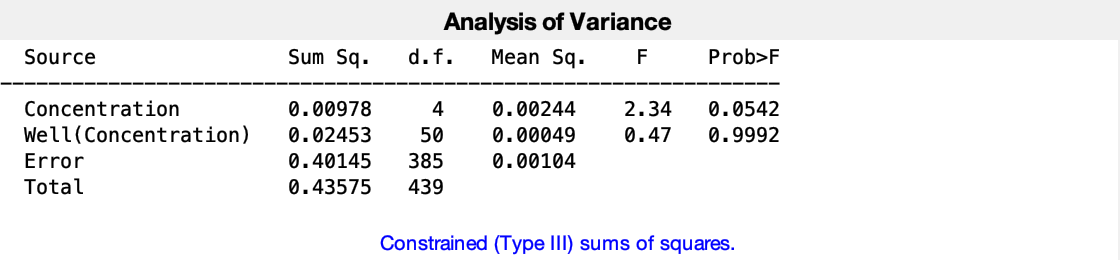

ANOVA on coefficient b_2 for all levels of concentration


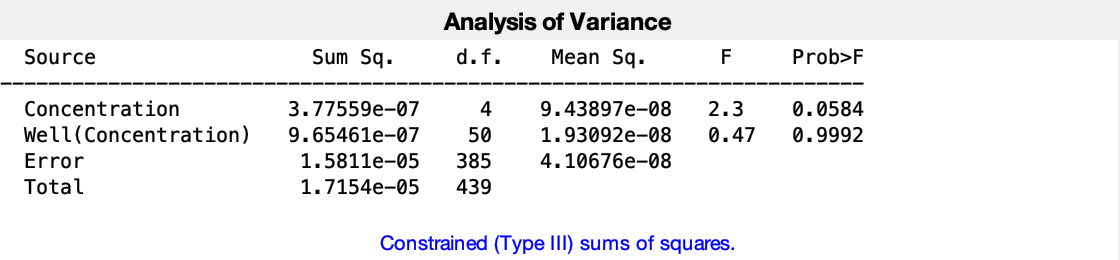

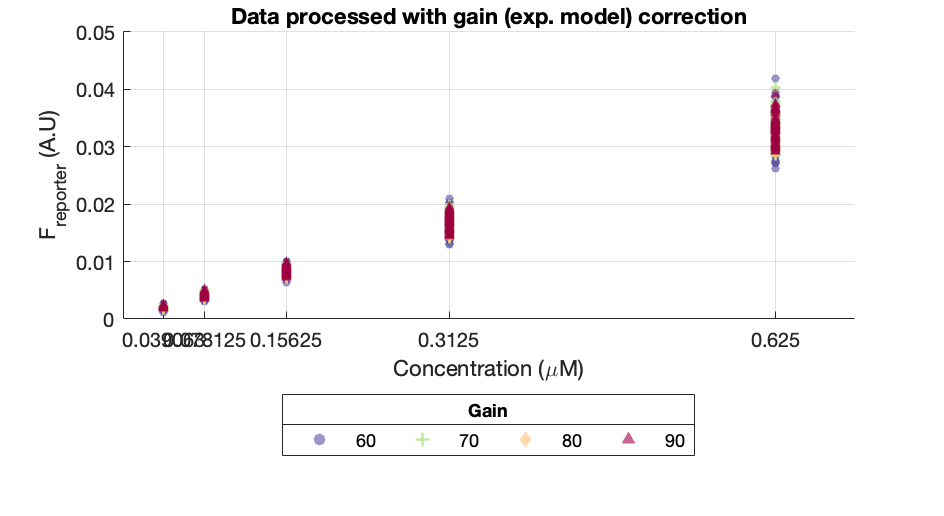

Fit f_UC and plot estimated concentration data (C): 


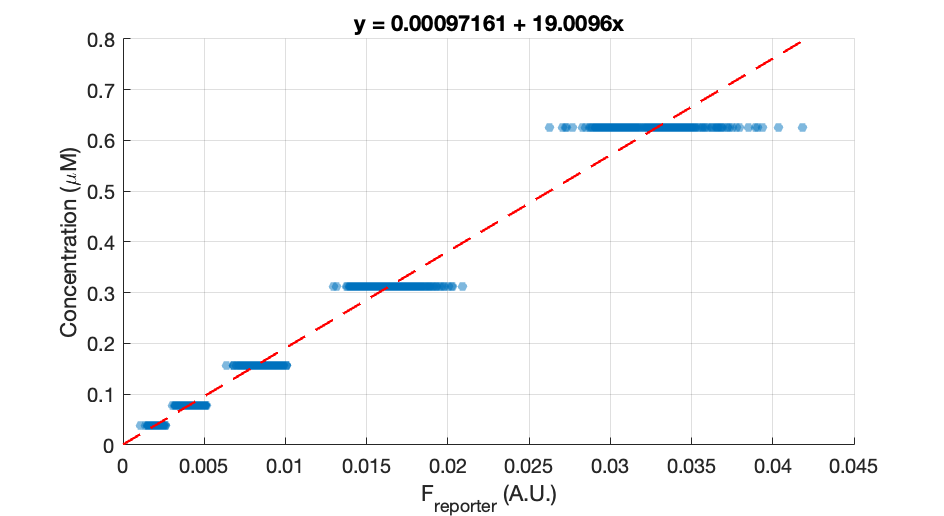

Analize the bias in the predictions and estimate the uncertainty in the predictions (s_Bias): 


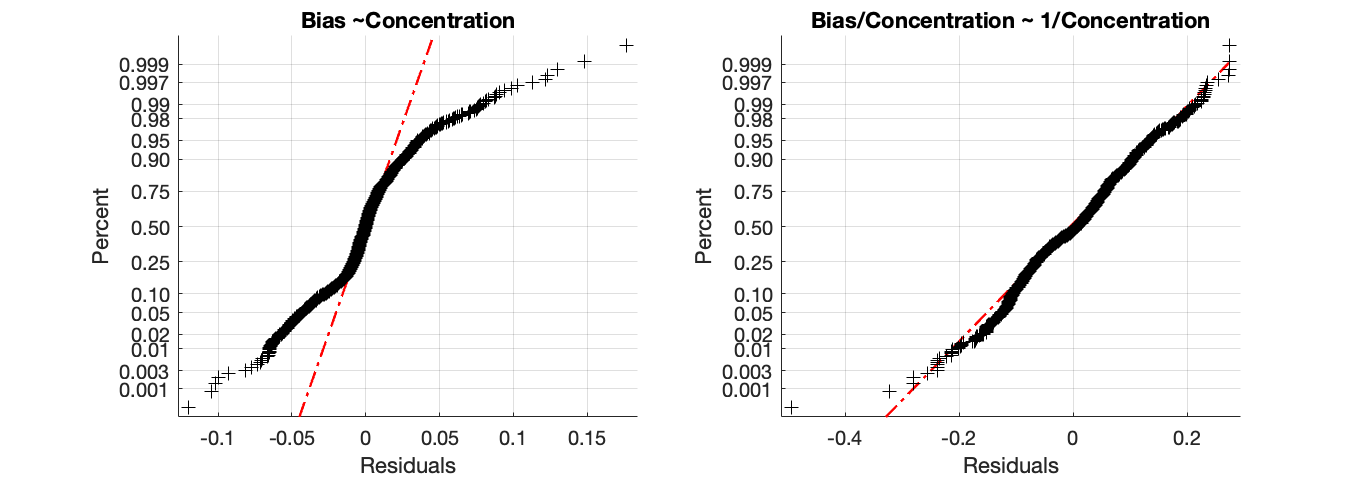

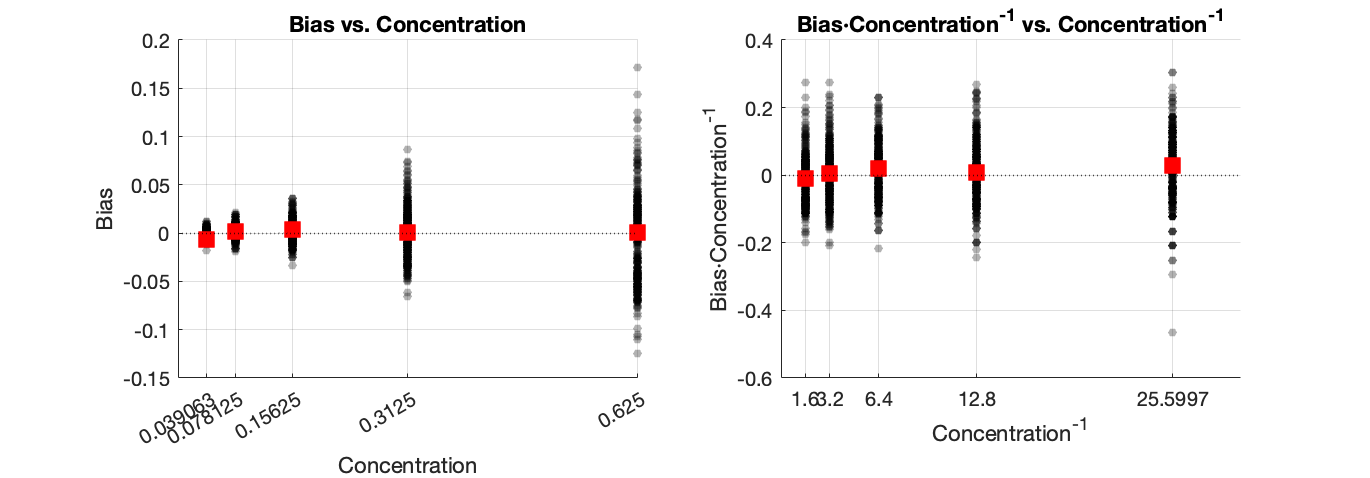

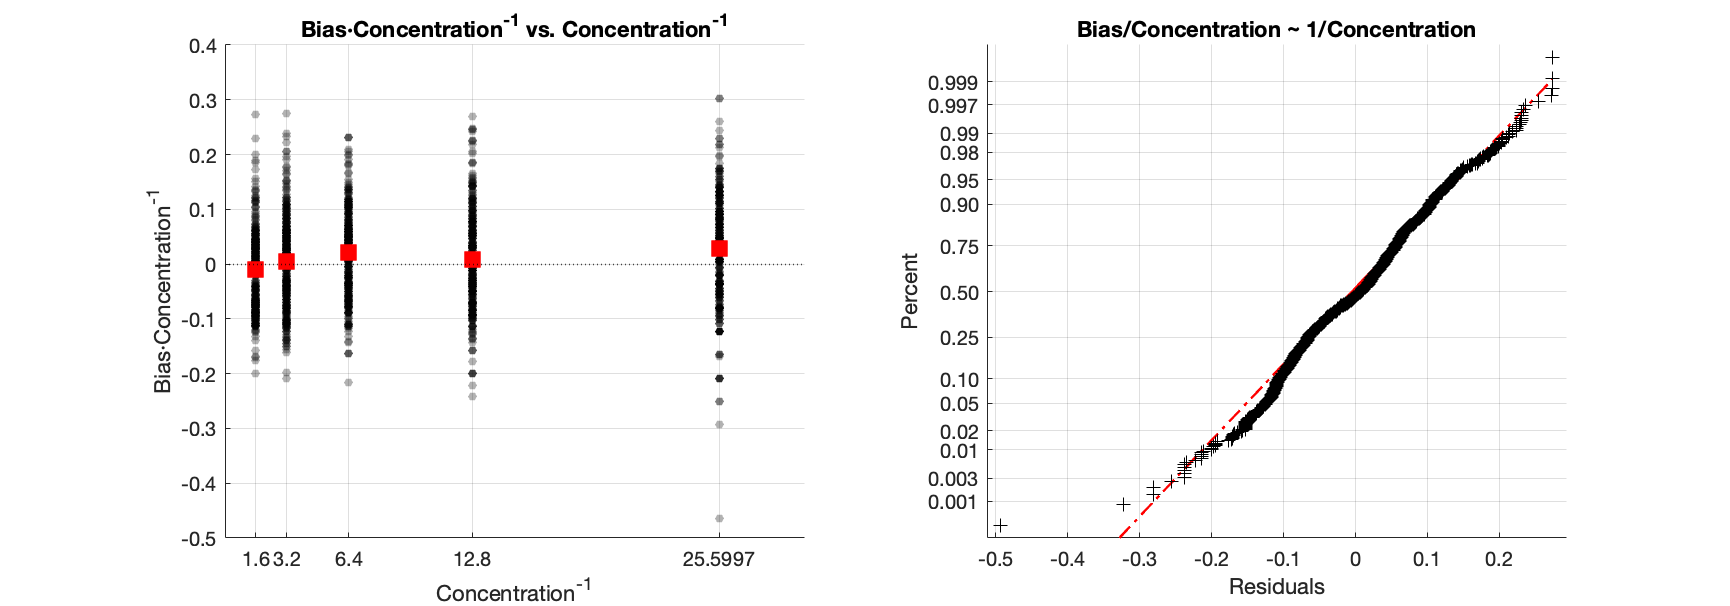

Compute error metrics for the Model Building step: 
    F_BLK (G = 60)    F_BLK (G = 70)    F_BLK (G = 80)    F_BLK (G = 90)      b1           b2             c0         c1       sBias      EDF 
    ______________    ______________    ______________    ______________    _______    ___________    __________    _____    ________    ____

          1                 2                 5                 9           0.19789    -0.00070272    0.00097161    19.01    0.086015    1758



[flu_data_PR2e2, modelPR2e2, calmetrics_PR2e2] = fit_platero_model(blk_data, ...
    flu_data_PR2e2, "PR_2e2");

## Step 3: Model Validation step

A 0 % of the observations was missing.
Plot the Validation dataset transformed to concentration units: 


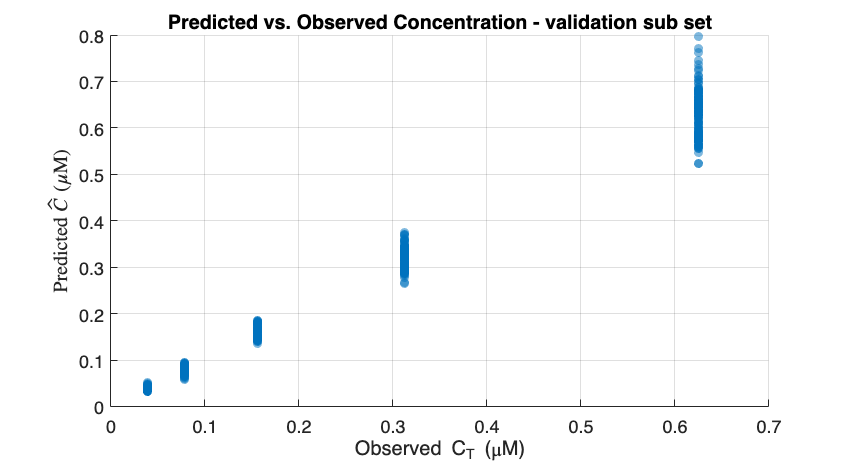

R&R Analysis: 
R & R Analysis on measurements for C = 0.039063


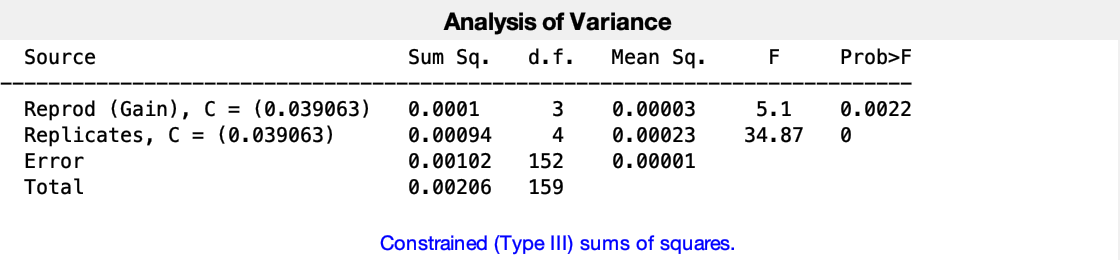

R & R Analysis on measurements for C = 0.078125


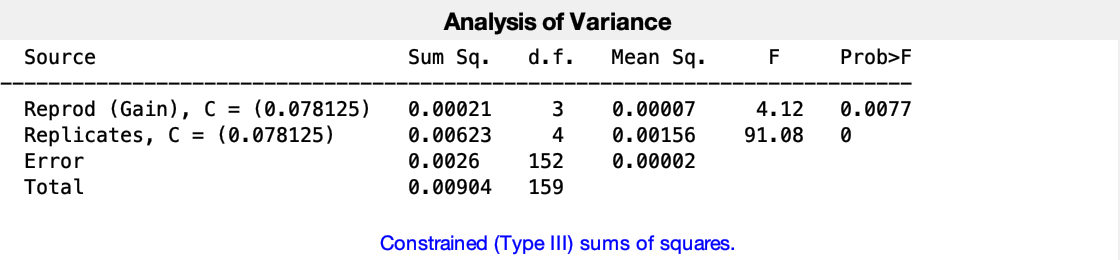

R & R Analysis on measurements for C = 0.15625


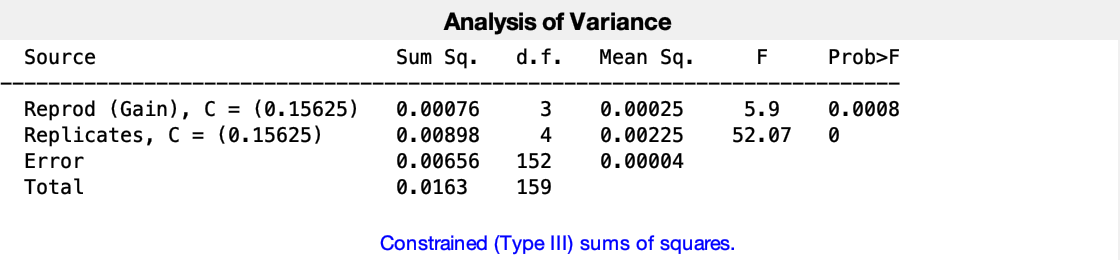

R & R Analysis on measurements for C = 0.3125


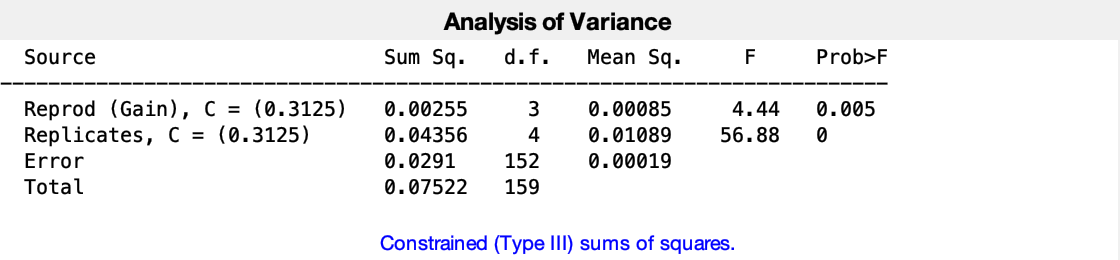

R & R Analysis on measurements for C = 0.625


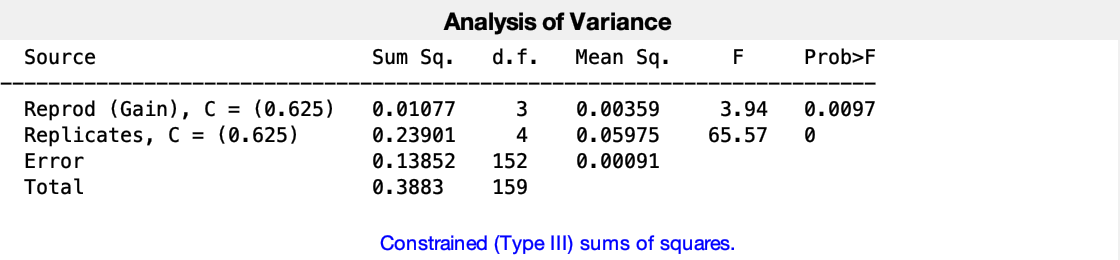

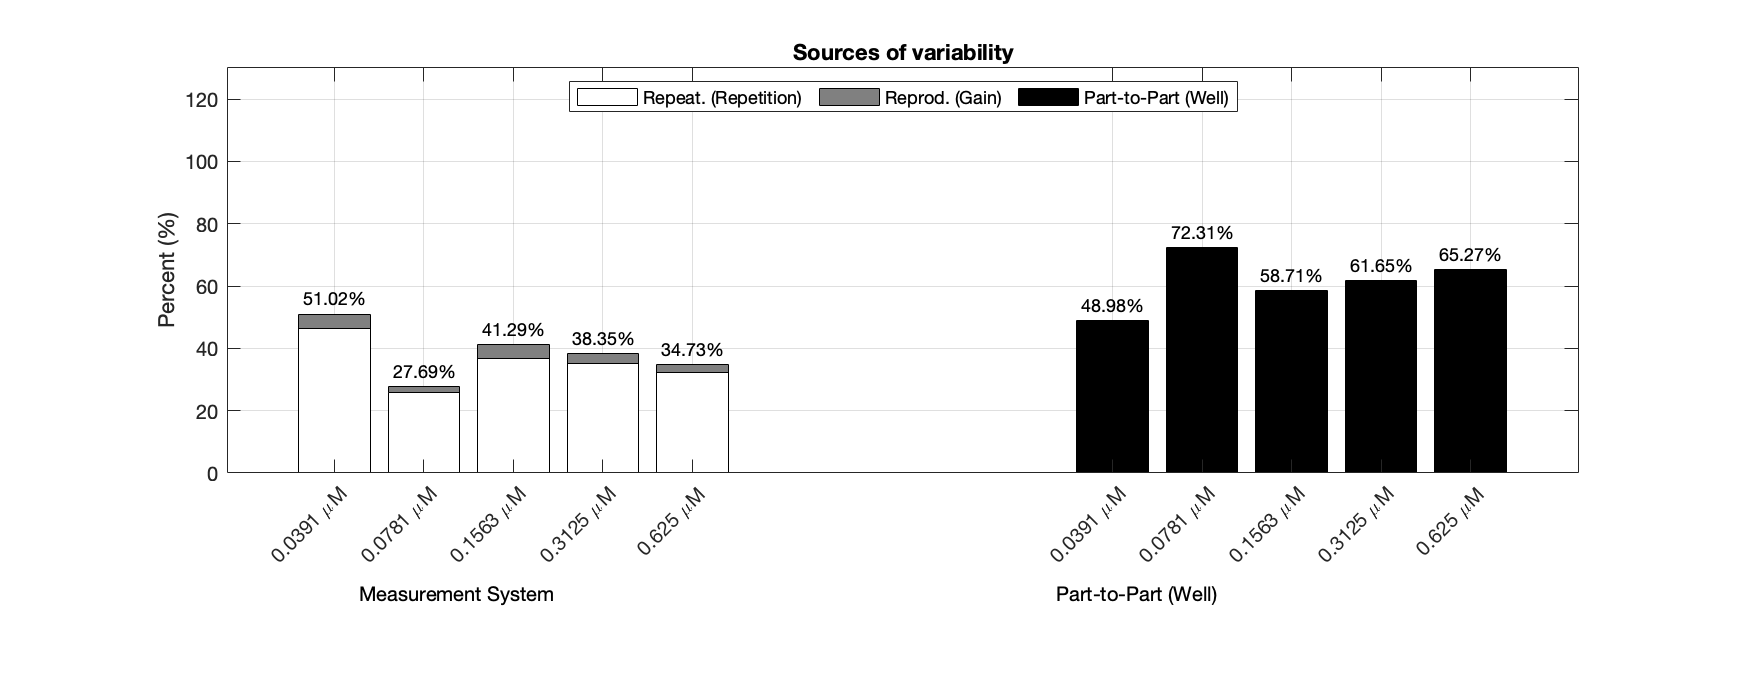

 
B&L Analysis: 


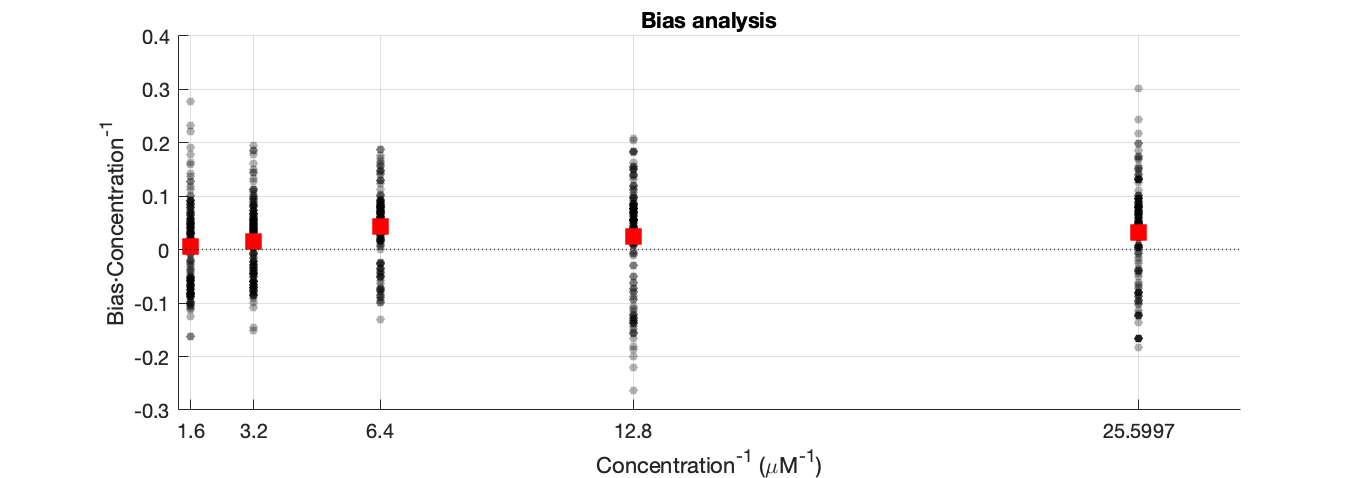

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)       0.01764     0.0043869    4.0211    6.3413e-05
    x1             0.00071458    0.00033201    2.1523      0.031675


Number of observations: 800, Error degrees of freedom: 798
Root Mean Squared Error: 0.082
R-squared: 0.00577,  Adjusted R-Squared: 0.00453
F-statistic vs. constant model: 4.63, p-value = 0.0317
-------------------------------------------------------------------
Contribution of model terms to the total bias variability:
Bias Model - linear term (%): 1.764 %
Bias Model - bias term (%): 4.9668 %
 
Confidence Intervals and Error metrics: 
        pctgeci: 96.3750
            mse: 6.3208e-0

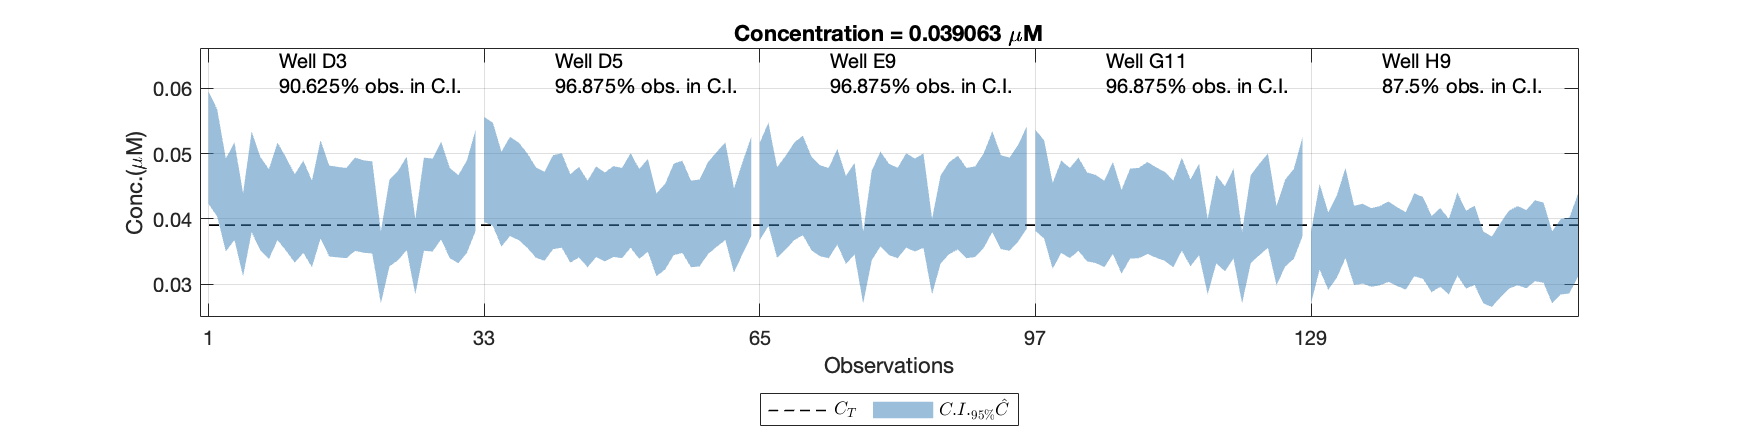

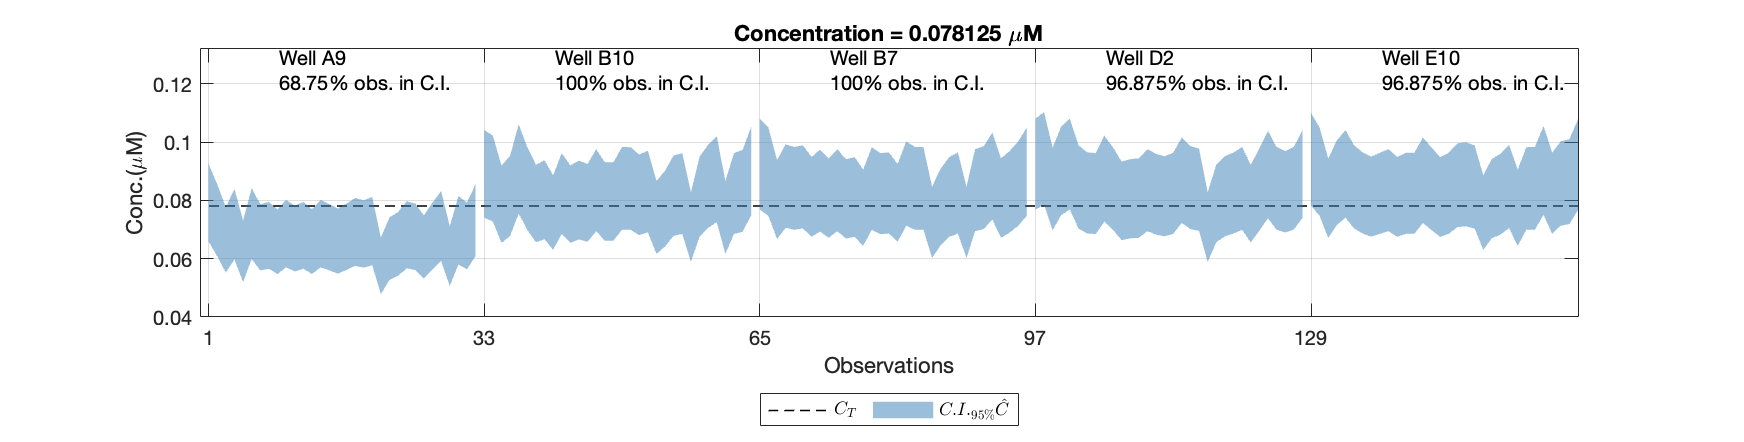

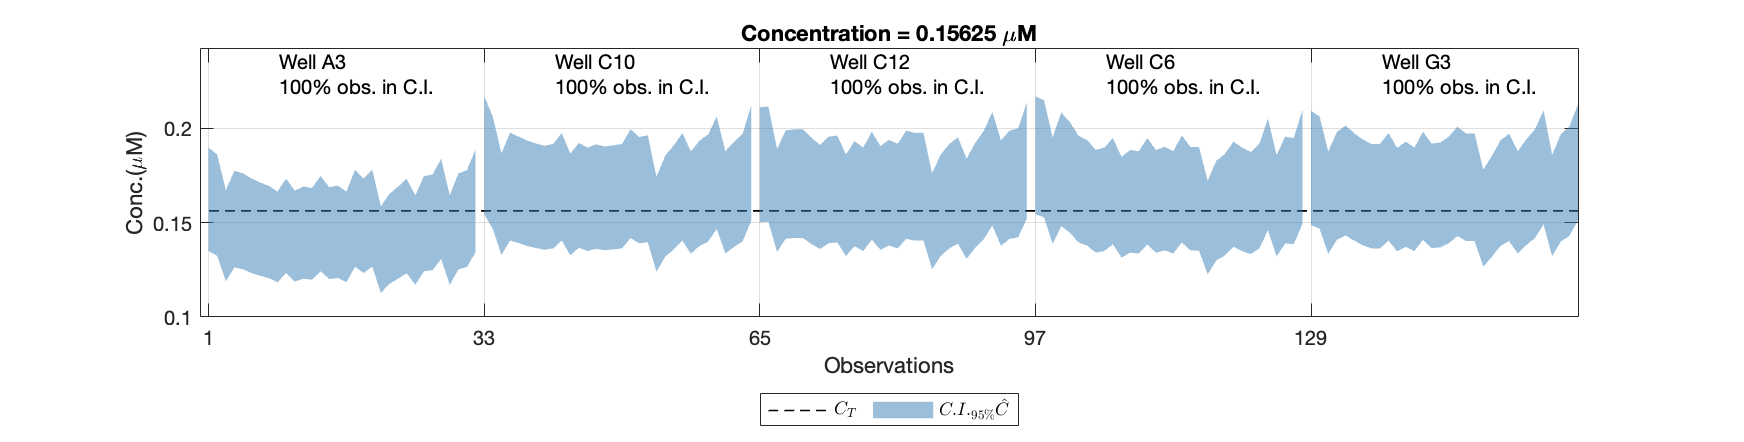

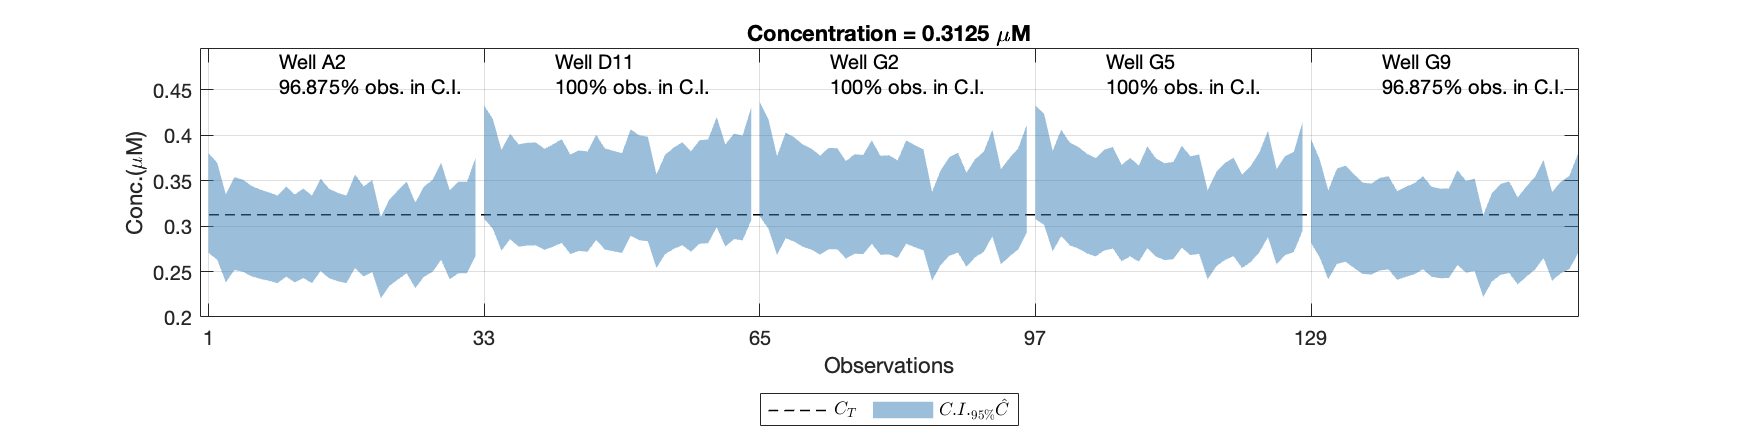

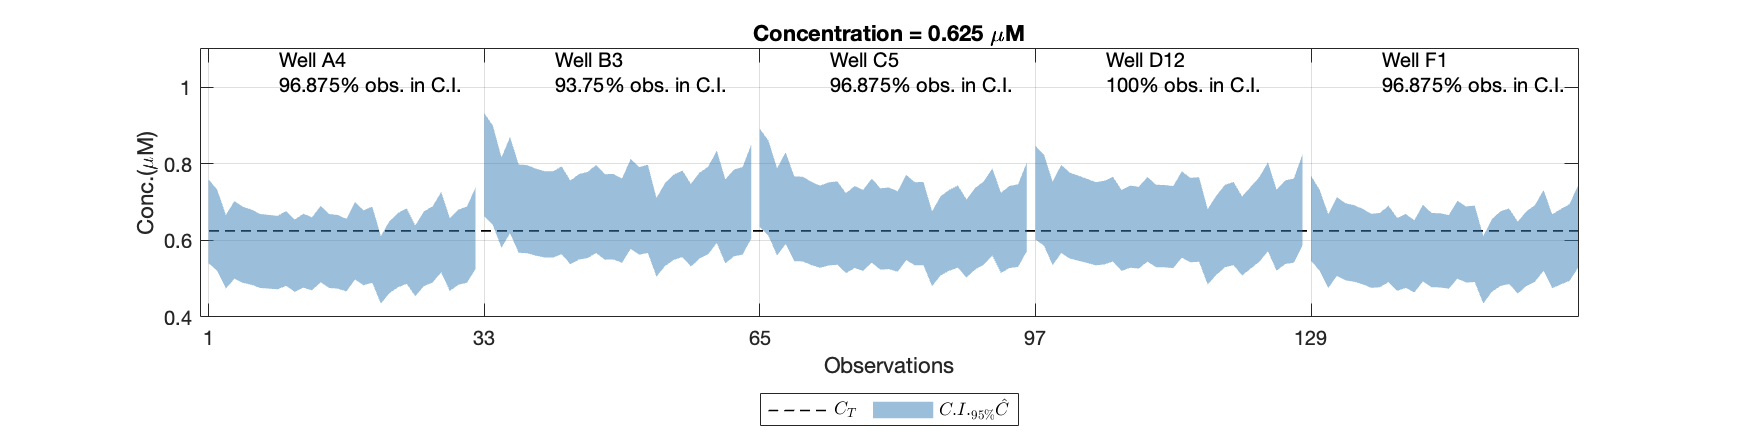

datagfp_val = load("validation_PR2e2.mat").datagfp_val;
uG = unique(flu_data_PR2e2.Gain);
uC = unique(flu_data_PR2e2.Concentration);
data_val_pr2e2 = datagfp_val(ismember(datagfp_val.Gain, uG),:);
G = unique(data_val_pr2e2.Gain);

% Assign the correspoding F_BLK values to each observation F_obs
data_val_pr2e2.Fblk = repmat(modelPR2e2{:,1:length(G)}', ...
    size(data_val_pr2e2,1)/length(G),1);

% Run the model on the validation set
[data_val_pr2e2, valmetrics_inrange, vprocv] = use_platero_model(data_val_pr2e2,...
    modelPR2e2,"PR_2e2");


% Comparison between calibration-set and validation-set metrics
% load(strcat(dirdatasave,'cal_results.mat'))
perftable = table([calmetrics_PR2e2.mse;valmetrics_inrange.mse],...
[calmetrics_PR2e2.minrelerror;valmetrics_inrange.minrelerror]*100,...
[calmetrics_PR2e2.maxrelerror;valmetrics_inrange.maxrelerror]*100,...
'RowNames',{'Calibration', 'Validation (within range)'},...
'VariableNames',{'MSE','Min.Rel.Error (%)','Max.Rel.Error (%)'});
display(perftable)

perftable = 2×3 table
                                    MSE        Min.Rel.Error (%)    Max.Rel.Error (%)
                                 __________    _________________    _________________

    Calibration                  0.00060951       0.00036951             46.403      
    Validation (within range)    0.00063208         0.061634             30.263      
